## Estimate model from square wave, validate with sine wave

Hyperparams

clear
validationStruct = load("tower_crane_square_test_bis_data.mat");
trainingStruct = load("tower_crane_sine_test_data.mat");
output = "arm"

output = "arm"

% sampling time
Ts = 0.002;

Preprocessing: cut off a few seconds

secondsToCutOff =4

secondsToCutOff = 4

% like this because matlab passes by value
trainingStruct = cutoffBeginning(trainingStruct, Ts, secondsToCutOff);
validationStruct = cutoffBeginning(validationStruct, Ts, secondsToCutOff);
% set options appropriately
tfestOpt = tfestOptions;
ssestOpt = ssestOptions;
initialCondZero = false

initialCondZero = logical
   0


if secondsToCutOff == 0
  initialCondZero = true
  tfestOpt.InitialCondition = 'zero';
  ssestOpt.InitialState = 'zero';  
end

load training and validation data

[t, y_arm, y_pendulum, u] = extract(trainingStruct);
[t_val, y_arm_val, y_pendulum_val, u_val] = extract(validationStruct);

constants

N = length(t);
% why this line?
t = (0:Ts:(N-1)*Ts)';

First for the crane arm

y = y_arm

y =    -0.1658
   -0.1689
   -0.1750
   -0.1781
   -0.1811
   -0.1873
   -0.1903
   -0.1934
   -0.1995
   -0.2026


y_val = y_arm_val

y_val =    -0.1965
   -0.1873
   -0.1750
   -0.1658
   -0.1566
   -0.1474
   -0.1381
   -0.1289
   -0.1228
   -0.1136



data = iddata(y, u, Ts);
data_val = iddata(y_val, u_val, Ts);

%Gest = tfest(data, 3, 1, 0, opt)
% only specify number of poles
Gest = tfest(data, 2, tfestOpt)

Gest =
 
  From input "u1" to output "y1":
      -1.373 s + 11.77
  -------------------------
  s^2 + 12.04 s + 1.385e-08
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 46.17%                   
FPE: 0.01855, MSE: 0.01848                       


See fit on training data

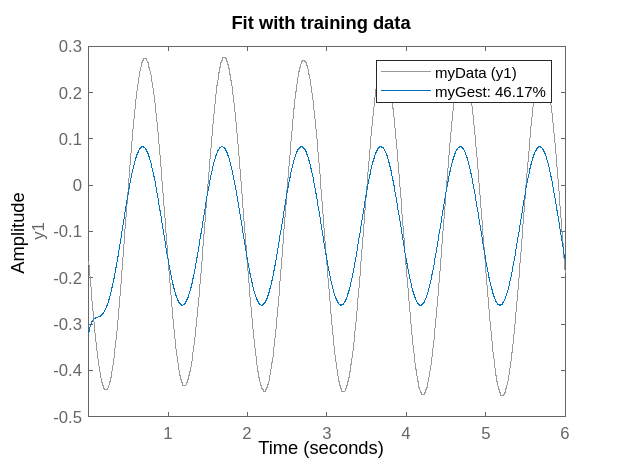

myCompare(data, Gest, initialCondZero)
title('Fit with training data')

See fit on validation data

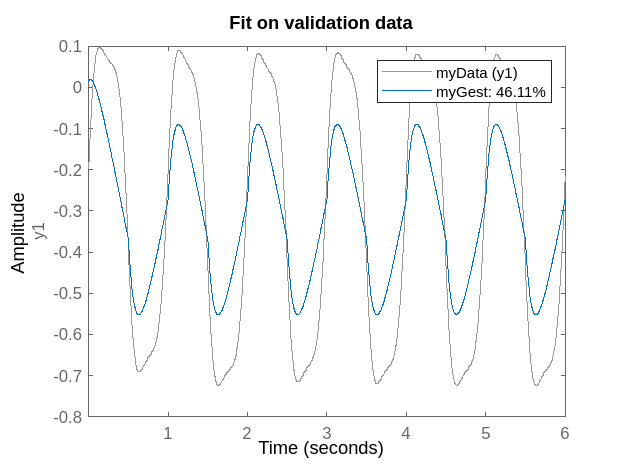

myCompare(data_val, Gest, initialCondZero)
title('Fit on validation data')

Estimate model with ssest

% telling initial state is zero in the options
Gss = ssest(data, 1:10, ssestOpt);
Gest_new = tf(Gss)

Gest_new =
 
  From input "u1" to output "y1":
     -6.831 s^2 - 2.903e05 s + 1.172e06
  -----------------------------------------
  s^3 + 4.778e04 s^2 + 9.133e05 s - 2.82e04
 
Continuous-time transfer function.



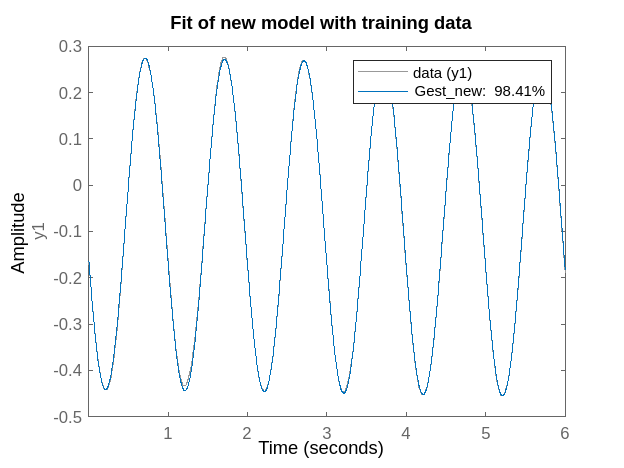

compare(data, Gest_new)
title('Fit of new model with training data')

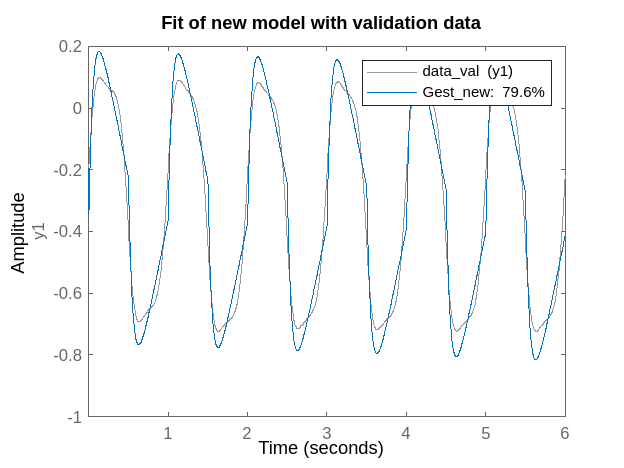

compare(data_val, Gest_new)
title('Fit of new model with validation data')

if we cut something off for training, compare the obtained model with the entire data

skipSec = 0

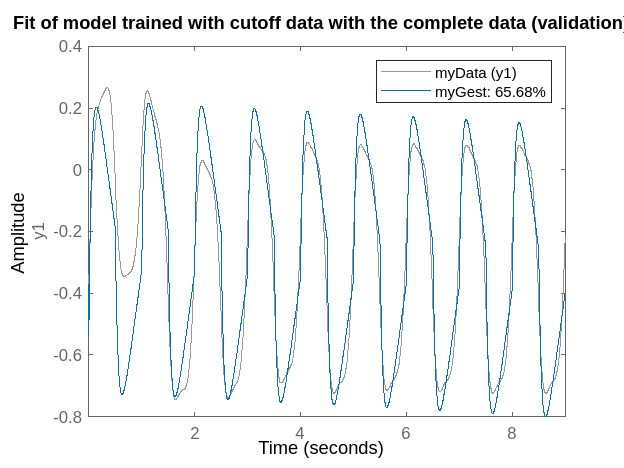

if not(initialCondZero) 
    skipSec = 0
    [t_c, y_arm_c, y_pendulum_c, u_c] = extractComplete(trainingStruct,Ts, 1);
    % TODO modular if arm or pendulum
    data_c = iddata(y_arm_c, u_c, Ts);
    myCompare(data_c, Gest_new, initialCondZero)
    title('Fit of model trained with cutoff data with the complete data')
    % same for the validation data
    [t_c, y_arm_c, y_pendulum_c, u_c] = extractComplete(validationStruct,Ts, 1);
    % TODO modular if arm or pendulum
    data_c = iddata(y_arm_c, u_c, Ts);
    myCompare(data_c, Gest_new, initialCondZero)
    title('Fit of model trained with cutoff data with the complete data (validation)')
end

Sanity check : system response to constant zero input

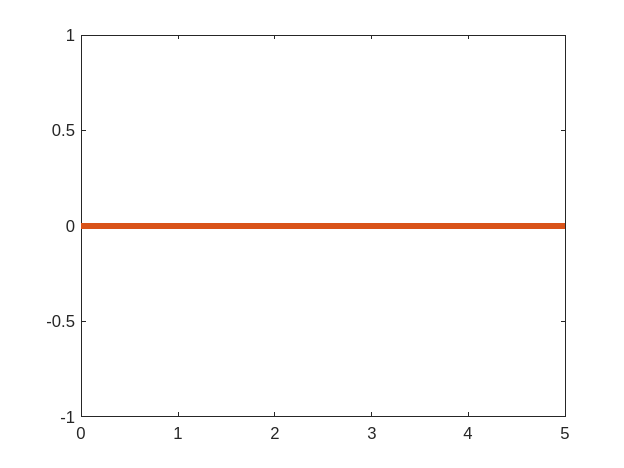

time = 0:Ts:5;
zero_input = zeros(length(time), 1);
zero_response = lsim(Gest_new, zero_input, time);

plot(time, [zero_input, zero_response], 'LineWidth', 4)

helper function

function [t, y_arm, y_pendulum, u] = extract(dataStruct)
    data_crane = dataStruct.data_crane;
    t = data_crane(1,:)';
    y_arm = data_crane(2,:)';
    y_pendulum = data_crane(3,:)';
    u = data_crane(4,:)';
end

% extract complete data in case the normal data is cut off
function [t, y_arm, y_pendulum, u] = extractComplete(dataStruct, Ts, skipSec)
    startIndex = (skipSec / Ts) + 1; 
    data_crane = dataStruct.data_crane_complete;
    t = data_crane(1, startIndex:end)';
    y_arm = data_crane(2, startIndex:end)';
    y_pendulum = data_crane(3, startIndex:end)';
    u = data_crane(4, startIndex:end)';
end

Compare with initial conditions as potentially zero

function myCompare(myData, myGest, initialCondZero)
    opt = compareOptions;
    if initialCondZero
        opt.InitialCondition = 'zero';
    end
    compare(myData, myGest, opt);  
end

cutoff transitory response

function result = cutoffBeginning(dataStruct, Ts, secondsToCutOff)
    if secondsToCutOff > 0
    dataStruct.data_crane_complete = dataStruct.data_crane;
    dataStruct.data_crane = dataStruct.data_crane(1:end, round(secondsToCutOff / Ts) + 1 : end);
    end
    result = dataStruct;
end